%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% TWO TANKS SYSTEM IDENTIFICATION %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% System SISO                   %
% Input DC Pump                 %
% Output Level Tank2 in cm      %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

clear
close all 
clc

data_train = readtable('SYS_IDENT.csv');
data_test  = readtable('Open_Loop.csv');
k = 4700;
Ts = 1; %Sampling time 


% Pre Processing Data Train 
u_train = data_train{:,5}; % Input data
u_train = u_train(1:k);
y_train = data_train{:,4}; % Output data
y_train = y_train(1:k);

if Ts~=1
    u_train = downsample(u_train,Ts);
    y_train = downsample(y_train,Ts);
end
t_train = 1:Ts:length(y_train);
%data_ident_train = iddata(y_train,u_train,Ts,"InputName","DC[%]","OutputName","Level2[cm]");
data_ident_train = iddata(y_train,u_train,Ts,"InputName","u1","OutputName","y1");

% data_ident_test = data_ident_train((ceil(length(y_train)/2)+1):length(y_train))
% data_ident_train = data_ident_train(1:round(length(y_train)/2))


% Pre Processing Data Test 
u_test = data_test{:,5}; % Input data
y_test = data_test{:,4}; % Output data

if Ts~=1
    u_test = downsample(u_test,Ts);
    y_test = downsample(y_test,Ts);
end
t_test = 1:Ts:length(y_test);
data_ident_test = iddata(y_test,u_test,Ts,"InputName","u1","OutputName","y1");

% figure,plot(y_test)
% figure,plot(y_train)

% LINEAR IDENTIFICATION 
nk = delayest(data_ident_train)
m1  = arx(data_ident_train,[2 2 0])
compare(m1,data_ident_train)
compare(m1,data_ident_test)

m2 = oe(data_ident_train,[2 2 0])
compare(m1,data_ident_train)
compare(m1,data_ident_test)
% 
G = get_plant_fdt(m2.F,m2.B,Ts)
G_s = d2c(G)
% 
s = tf('s');
G_1 = (0.0001251)/(s^2+0.03245*s+0.000121)
G_2 = c2d(G_1,1)
G_3 = d2c(G_2,"zoh")


m4 = arx(data_ident_train_detrend,[2 2 1])
compare(m1,data_ident_train_detrend)
compare(m1,data_ident_test)

% select best order by Akaike's information criterion (AIC)
V = arxstruc(data_ident_train,data_ident_test,struc(1:10, 1:10, 1:12));
nn = selstruc(V,'aic')
nn_1 = selstruc(V,'mdl')

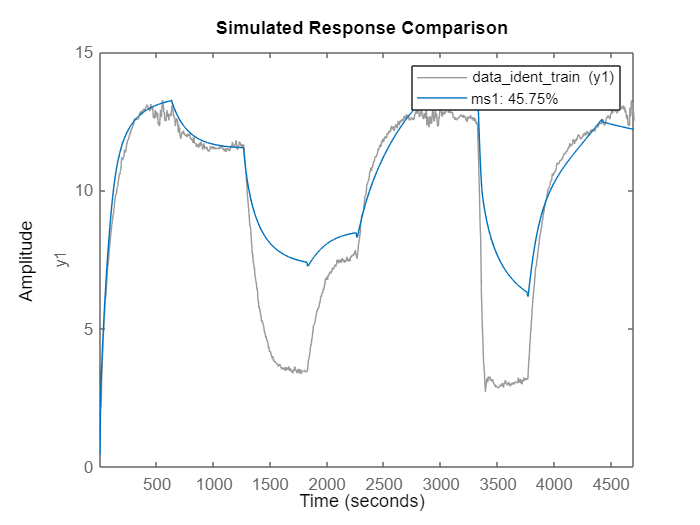

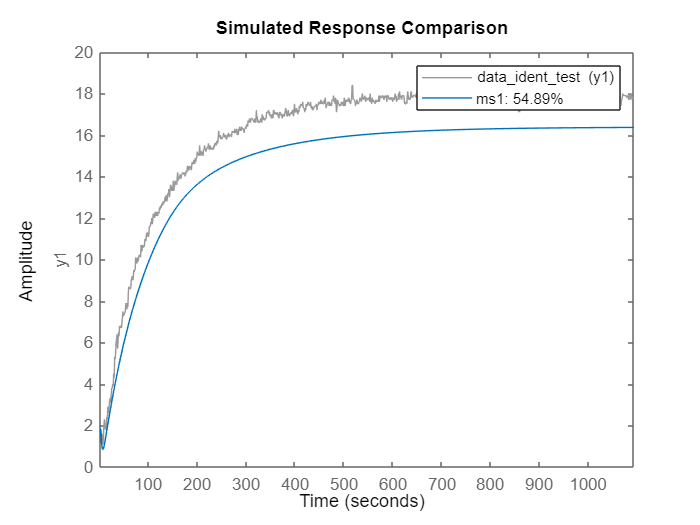

mhw1 =
Hammerstein-Wiener model with 1 output and 1 input
 Linear transfer function corresponding to the orders nb = 2, nf = 2, nk = 1
 Input nonlinearity: Piecewise linear with 10 break-points
 Output nonlinearity: absent
Sample time: 1 seconds

Status:                                                     
Estimated using NLHW on time domain data "data_ident_train".
Fit to estimation data: 85.68%                              
FPE: 0.2615, MSE: 0.2587


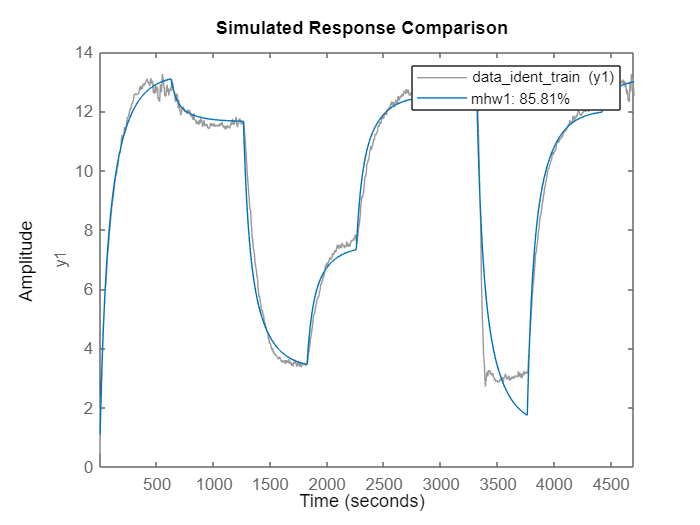

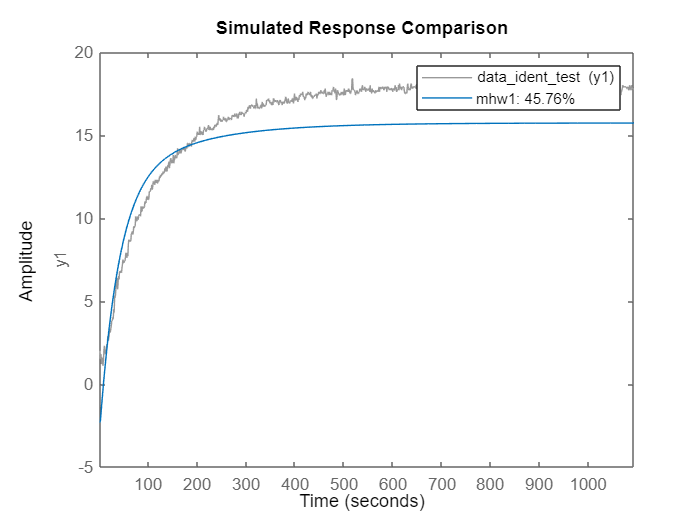

ms =
  Discrete-time identified state-space model:
    x(t+Ts) = A x(t) + B u(t) + K e(t)
       y(t) = C x(t) + D u(t) + e(t)
 
  A = 
            x1       x2
   x1        0        1
   x2  -0.9778    1.978
 
  B = 
             u1
   x1  0.002921
   x2  0.002872
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
  K = 
          y1
   x1  1.081
   x2   1.13
 
Sample time: 1 seconds
  
Parameterization:
   CANONICAL form with indices: 2.
   Feedthrough: none
   Disturbance component: estimate
   Number of free coefficients: 6
   Use "idssdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                      
Estimated using N4SID on time domain data "data_ident_train".
Fit to estimation data: 98.86% (prediction focus)            
FPE: 0.001658, MSE: 0.001653                                 


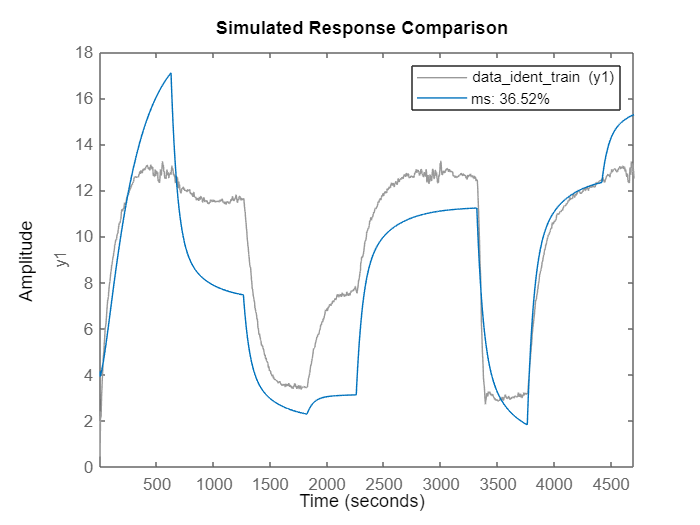

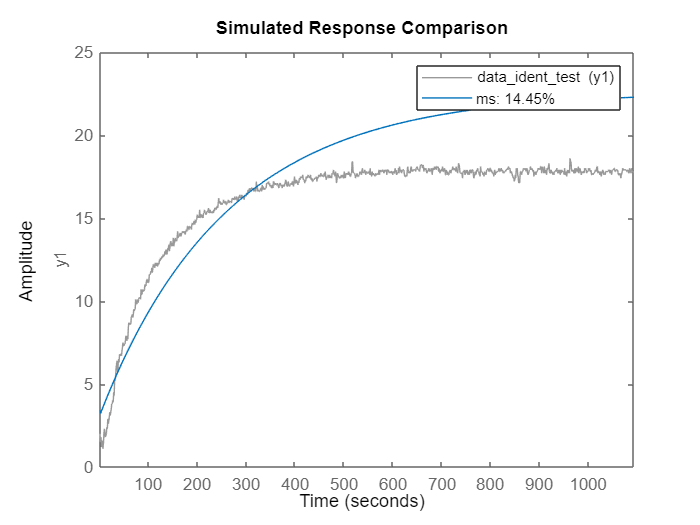

% Non Linear Identification
mw1 = nlarx(data_ident_train,[1 1 11], idWaveletNetwork(10))

NLFcn = mw1.OutputFcn
NLFcn.NonlinearFcn.NumberOfUnits

G_plant_1 =
 
          0.0001251
  --------------------------
  s^2 + 0.03245 s + 0.000121
 
Continuous-time transfer function.



compare(data_ident_train,mw1) 
compare(data_ident_test,mw1) 

G_z_1 =
 
  6.188e-05 z + 6.121e-05
  -----------------------
  z^2 - 1.968 z + 0.9681
 
Sample time: 1 seconds
Discrete-time transfer function.



resid(data_ident_test,mw1)

G_z_2 =
 
  0.0002449 z + 0.0002396
  -----------------------
  z^2 - 1.937 z + 0.9372
 
Sample time: 2 seconds
Discrete-time transfer function.



%plot(mw1)

G_z_3 =
 
  0.0005451 z + 0.0005277
  -----------------------
  z^2 - 1.906 z + 0.9072
 
Sample time: 3 seconds
Discrete-time transfer function.



R = linearRegressor([data_ident_train.OutputName; data_ident_train.InputName],{1:3, 2});

G_z_4 =
 
  0.0009587 z + 0.0009181
  -----------------------
  z^2 - 1.876 z + 0.8783
 
Sample time: 4 seconds
Discrete-time transfer function.



mw2_a = nlarx(data_ident_train, R, idWaveletNetwork(10));

G_z_5 =
 
  0.001482 z + 0.001404
  ----------------------
  z^2 - 1.847 z + 0.8502
 
Sample time: 5 seconds
Discrete-time transfer function.



getreg(mw2_a)

G_z_6 =
 
  0.002112 z + 0.001979
  ----------------------
  z^2 - 1.819 z + 0.8231
 
Sample time: 6 seconds
Discrete-time transfer function.



compare(data_ident_train,mw2_a)

G_pid_z_1 =
 
              Ts            z-1 
  Kp + Ki * ------ + Kd * ------
              z-1           Ts  

  with Kp = 1.85, Ki = 0.0117, Kd = 61.2, Ts = 1
 
Sample time: 1 seconds
Discrete-time PID controller in parallel form.



compare(data_ident_test,mw2_a)

G_pid_z_2 =
 
              Ts            z-1 
  Kp + Ki * ------ + Kd * ------
              z-1           Ts  

  with Kp = 1.78, Ki = 0.0112, Kd = 60.3, Ts = 2
 
Sample time: 2 seconds
Discrete-time PID controller in parallel form.



ms1 = nlarx(data_ident_train,[4 4 1]);

G_pid_z_3 =
 
              Ts            z-1 
  Kp + Ki * ------ + Kd * ------
              z-1           Ts  

  with Kp = 1.86, Ki = 0.0117, Kd = 62.9, Ts = 3
 
Sample time: 3 seconds
Discrete-time PID controller in parallel form.



compare(data_ident_train,ms1)

G_pid_z_4 =
 
              Ts            z-1 
  Kp + Ki * ------ + Kd * ------
              z-1           Ts  

  with Kp = 1.85, Ki = 0.0115, Kd = 63.3, Ts = 4
 
Sample time: 4 seconds
Discrete-time PID controller in parallel form.



compare(data_ident_test,ms1)

G_pid_z_5 =
 
              Ts            z-1 
  Kp + Ki * ------ + Kd * ------
              z-1           Ts  

  with Kp = 1.84, Ki = 0.0105, Kd = 71.7, Ts = 5
 
Sample time: 5 seconds
Discrete-time PID controller in parallel form.



mhw1 = nlhw(data_ident_train, [2 2 1],idPiecewiseLinear, [])

G_pid_z_6 =
 
              Ts            z-1 
  Kp + Ki * ------ + Kd * ------
              z-1           Ts  

  with Kp = 1.99, Ki = 0.0113, Kd = 77.3, Ts = 6
 
Sample time: 6 seconds
Discrete-time PID controller in parallel form.




compare(data_ident_train,mhw1)
compare(data_ident_test,mhw1)

G = get_plant_fdt(mhw1.LinearModel.B,mhw1.LinearModel.F,Ts)

G_1 =
 
  0.00379 z^3 - 0.003717 z^2 - 0.003709 z + 0.003637
  --------------------------------------------------
       1.004 z^3 - 2.972 z^2 + 2.932 z - 0.9644
 
Sample time: 1 seconds
Discrete-time transfer function.



G_s = d2c(G,'zoh')

G_2 =
 
  0.007387 z^3 - 0.007108 z^2 - 0.007074 z + 0.006807
  ---------------------------------------------------
       1.007 z^3 - 2.944 z^2 + 2.867 z - 0.9304
 
Sample time: 2 seconds
Discrete-time transfer function.



ms = n4sid(data_ident_train,'best','Ts',1,'Form','Canonical')

G_3 =
 
  0.01142 z^3 - 0.01077 z^2 - 0.01071 z + 0.0101
  ----------------------------------------------
     1.011 z^3 - 2.917 z^2 + 2.803 z - 0.8971
 
Sample time: 3 seconds
Discrete-time transfer function.



compare(data_ident_train,ms)

G_4 =
 
  0.01517 z^3 - 0.01404 z^2 - 0.01392 z + 0.01287
  -----------------------------------------------
      1.015 z^3 - 2.89 z^2 + 2.741 z - 0.8654
 
Sample time: 4 seconds
Discrete-time transfer function.



compare(data_ident_test,ms)

G_5 =
 
  0.02125 z^3 - 0.01965 z^2 - 0.01908 z + 0.01763
  -----------------------------------------------
     1.021 z^3 - 2.867 z^2 + 2.679 z - 0.8326
 
Sample time: 5 seconds
Discrete-time transfer function.



G_6 =
 
  0.02722 z^3 - 0.02474 z^2 - 0.02392 z + 0.02171
  -----------------------------------------------
     1.027 z^3 - 2.844 z^2 + 2.618 z - 0.8014
 
Sample time: 6 seconds
Discrete-time transfer function.



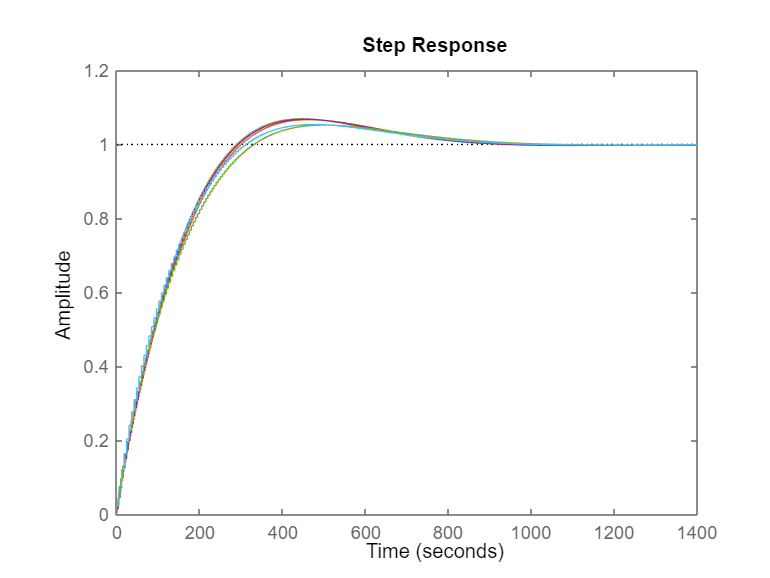

mhw1 = nlhw(data_ident_train, [10 1 5], [],[])

compare(data_ident_train,mhw1)
compare(data_ident_test,mhw1)

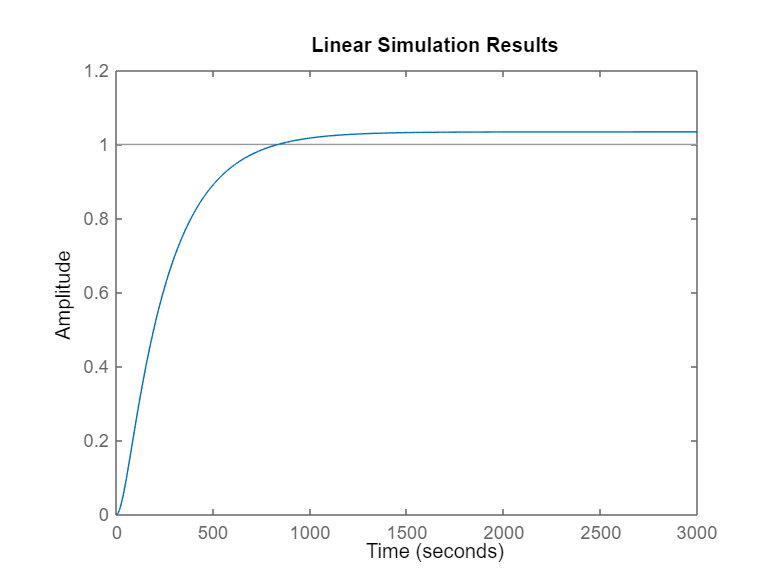


sys = n4sid(data_train,2)
sys_1 = n4sid(data_test,2)


G = tf(sys)
t = 0:2000;
u = 100*ones(length(t),1);

G_z_1 =
 
  6.188e-05 z + 6.121e-05
  -----------------------
  z^2 - 1.968 z + 0.9681
 
Sample time: 1 seconds
Discrete-time transfer function.



lsim(G,u,t)

Ts = 1

z =
 
  z
 
Sample time: 1 seconds
Discrete-time transfer function.



names = [data_ident_train.OutputName,data_ident_train.InputName]

G_pid_1 =
 
  2.75 z - 2.705
  --------------
      z - 1
 
Sample time: 1 seconds
Discrete-time transfer function.



L = linearRegressor(names,{1:2,0:2})

num_1 = 1×1 cell array
    {[2.7500 -2.7047]}


den_1 = 1×1 cell array
    {[1 -1]}


NL1 = nlarx(data_ident_train,L,idLinear)

num_2 = 1×1 cell array
    {[0 6.1878e-05 6.1213e-05]}


den_2 = 1×1 cell array
    {[1 -1.9680 0.9681]}


compare(data_ident_train,NL1);
compare(data_ident_test,NL1);

L = linearRegressor(names,{1:3,0:2})
C = customRegressor({'y1'},{1},@(y)sqrt(y));
R = [L,C];
NL1 = nlarx(data_ident_train,R,idLinear)
compare(data_ident_train,NL1);
compare(data_ident_test,NL1);

%G_pid = pidtune(G,'PI')
% PID = pidtune(G,'PI');
% z = tf('z',1);
% PID.Kp =2.75;
% PID.Ki =0.0453;
% PID.Kd =0;
% G_pid = PID.Kp +  PID.Ki*(Ts/(z-1)) + PID.Kd*((z-1)/Ts);


% From report 
s=tf('s');
G_plant_1 = (0.0001251)/(s^2 + 0.03245*s+0.000121)
% discretize
G_z_1 = c2d(G_plant_1,1,'zoh')
G_z_2 = c2d(G_plant_1,2,'zoh')
G_z_3 = c2d(G_plant_1,3,'zoh')
G_z_4 = c2d(G_plant_1,4,'zoh')
G_z_5 = c2d(G_plant_1,5,'zoh')
G_z_6 = c2d(G_plant_1,6,'zoh')
% step(G_z_1,G_z_2,G_z_3,G_z_4,G_z_5,G_z_6)
G_pid_z_1 = pidtune(G_z_1,'PID')
G_pid_z_2 = pidtune(G_z_2,'PID')
G_pid_z_3 = pidtune(G_z_3,'PID')
G_pid_z_4 = pidtune(G_z_4,'PID')
G_pid_z_5 = pidtune(G_z_5,'PID')
G_pid_z_6 = pidtune(G_z_6,'PID')

Ts = 1
z=tf('z',Ts)
G_pid_1 = 2.75 +0.0453*(Ts/(z-1)) + 0*(z-1/Ts);
Ts = 2;
z=tf('z',Ts)
G_pid_2 = G_pid_z_2.Kp +G_pid_z_2.Ki*(Ts/(z-1)) + G_pid_z_2.Kd*(z-1/Ts)
Ts = 3;
z=tf('z',Ts)
G_pid_3 = G_pid_z_2.Kp +G_pid_z_2.Ki*(Ts/(z-1)) + G_pid_z_2.Kd*(z-1/Ts)
Ts = 4;
z=tf('z',Ts)
G_pid_4 = G_pid_z_3.Kp +G_pid_z_3.Ki*(Ts/(z-1)) + G_pid_z_3.Kd*(z-1/Ts)
Ts = 5;
z=tf('z',Ts)
G_pid_5 = G_pid_z_1.Kp +G_pid_z_1.Ki*(Ts/(z-1)) + G_pid_z_1.Kd*(z-1/Ts)
Ts = 6;
z=tf('z',Ts)
G_pid_6 = G_pid_z_1.Kp +G_pid_z_1.Ki*(Ts/(z-1)) + G_pid_z_1.Kd*(z-1/Ts)


G_1 = feedback(G_pid_z_1*G_z_1,1)
G_2 = feedback(G_pid_z_2*G_z_2,1)
G_3 = feedback(G_pid_z_3*G_z_3,1)
G_4 = feedback(G_pid_z_4*G_z_4,1)
G_5 = feedback(G_pid_z_5*G_z_5,1)
G_6 = feedback(G_pid_z_6*G_z_6,1)
step(G_1,G_2,G_3,G_4,G_5,G_6)

G1_info = stepinfo(G_1)
G2_info = stepinfo(G_2)
G3_info = stepinfo(G_3)
G4_info = stepinfo(G_4)
G5_info = stepinfo(G_5)
G6_info = stepinfo(G_6)

t_3 = 0:3:2000;
t_6 = 0:6:2000;
u_3 = 10*ones(length(t_3),1);
u_6 = 10*ones(length(t_6),1);

lsim(G_3,u_3,t_3)
hold on
lsim(G_6,u_6,t_6)



t = 0:3000;
u = ones(length(t),1);
lsim(G_plant_1,u,t)


G_z_1 = c2d(G_plant_1,1,'zoh')
Ts = 1
z=tf('z',Ts)
G_pid_1 = 2.75 +0.0453*(Ts/(z-1)) + 0*(z-1/Ts)
[num_1,den_1] = tfdata(G_pid_1)
[num_2,den_2] = tfdata(G_z_1)
